co = 4


=== Running Experiment 1 ===


ans =   TrainingOptionsSGDM with properties:

                        Momentum: 0.9000
                InitialLearnRate: 0.1000
                       MaxEpochs: 150
               LearnRateSchedule: 'piecewise'
             LearnRateDropFactor: 0.5000
             LearnRateDropPeriod: 15
                   MiniBatchSize: 256
                         Shuffle: 'every-epoch'
             CheckpointFrequency: 1
         CheckpointFrequencyUnit: 'epoch'
                  SequenceLength: 'longest'
        PreprocessingEnvironment: 'serial'
                L2Regularization: 1.0000e-03
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                         Verbose: 0
                VerboseFrequency: 50
                  ValidationData: [1×1 augmentedImageDatastore]
             ValidationFrequency: 50
              ValidationPatience: 25
             ObjectiveMetricName: 


=== Running Training 1 ===


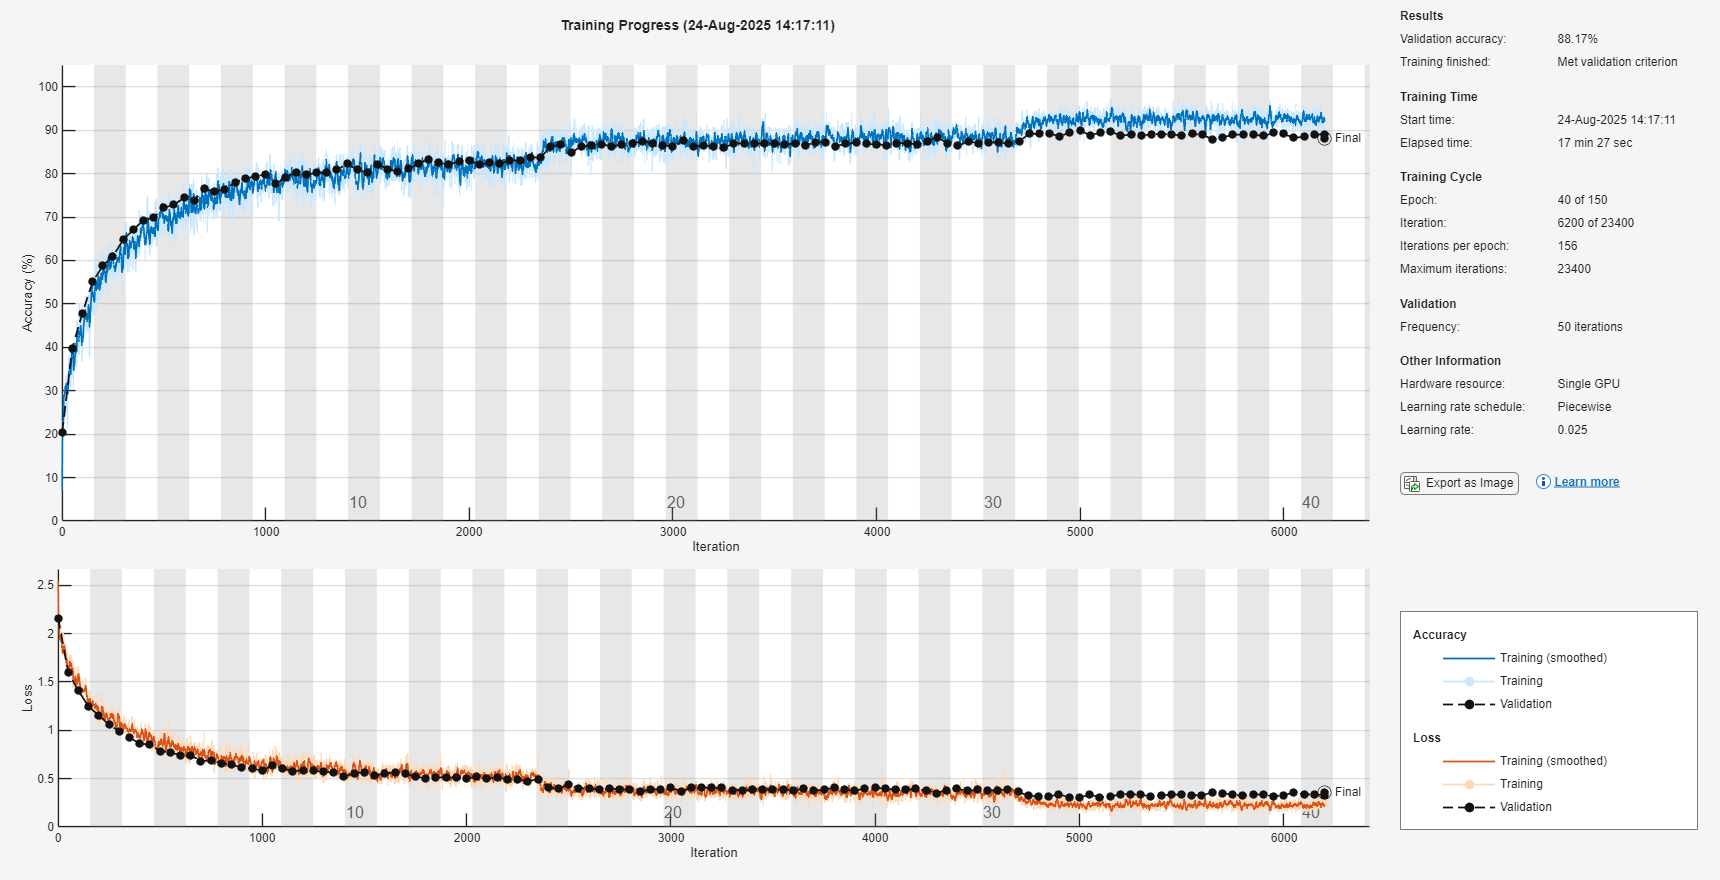


=== Done Training 1 ===


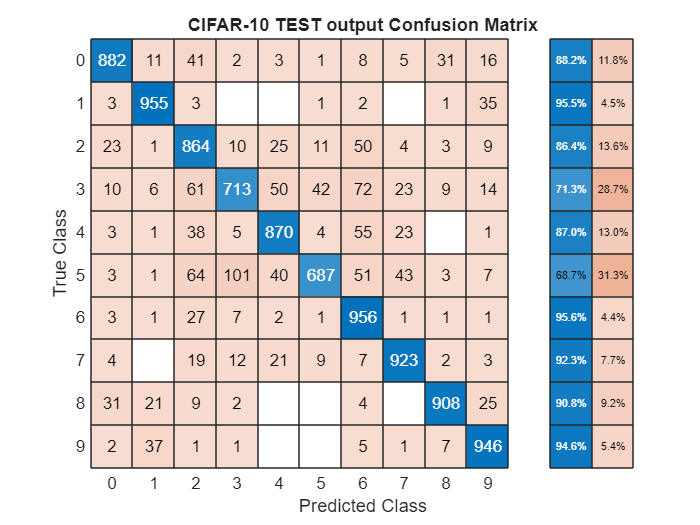

Overall Accuracy (from CM): 87.04%


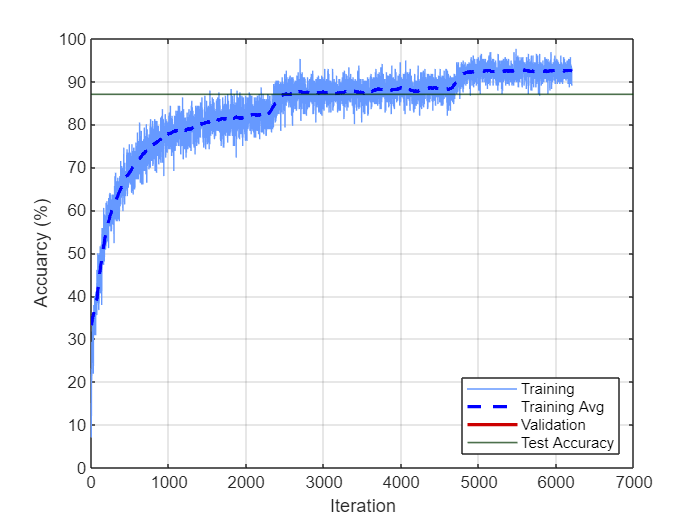

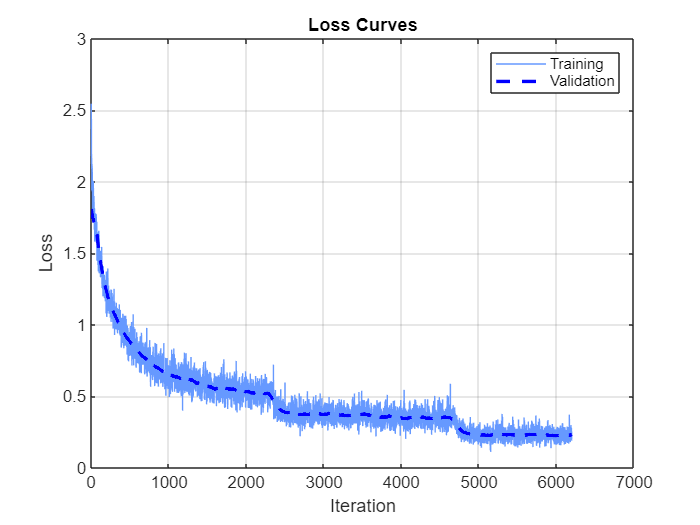

Not enough input arguments.

Error in conv (line 26)
if ~isvector(a) || ~isvector(b)

clearvars
global options
% Define ranges
Method          = ["sgdm","adam","rmsprop"];
initLearnRate   = [0.1 0.01 0.001];
MaxEpochs       = 150;  
MiniBatchSize   = [256 128 64];
Momentum        = 0.9;
conv            = 4;

% Counter for experiment tracking
expNum = 1;

loadtrainingdata

for lr = initLearnRate
    for mb = MiniBatchSize
        for mm = Method
            %for co = conv
            co = conv
            fprintf('\n=== Running Experiment %d ===\n', expNum);

            clearvars -except lr mb mm co conv ...
                options expNum ...
                trainImages valImages testImages ...
                trainLabels valLabels testLabels ...
                imageAugmenter trainDS valDS testDS ...
                initLearnRate MaxEpochs MiniBatchSize ...
                Momentum Method

            createTrainingOptions(mm, lr,15, MaxEpochs, mb, valDS,50,Momentum,1)
             
            switch co
                case 2
                    conv2layers
                case 3
                    conv3layers
                case 4
                    conv4layers
            end
      
            runfile

            expNum = expNum + 1;
            %end
        end
    end
end